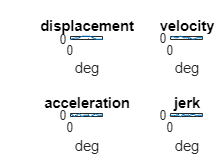

tiledlayout(2,2)
syms deg(t);
omega=500*2*pi/60;
nexttile
harmonic=(0.010/2)*(1-cos(pi*deg/60));
dwell1=0.010;
cycloid=0.015*((deg-80)/70-sin(2*pi*(deg-80)/70)/(2*pi))+0.010;
dwell2=0.025;
poly=-0.025*(10*(deg-200).^3/100.^3-15*(deg-200).^4/100.^4+6*(deg-200).^5/100.^5)+0.025;
dwell3=0;
y=piecewise(deg<60, harmonic, 60<deg<80, dwell1, 80<deg<150, cycloid, 150<deg<200, dwell2, 200<deg<300, poly, 300<deg<360, dwell3);
y=subs(y,deg,t);
fplot(y);
xlim([0 360]);
title("displacement")
ylabel("m")
xlabel("deg")

nexttile
vharmonic=subs(diff(harmonic),diff(deg),omega);
vdwell1=0;
vcycloid=subs(diff(cycloid),diff(deg),omega);
vdwell2=0;
vpoly=subs(diff(poly),diff(deg),omega);
vdwell3=0;
v=piecewise(0<deg<60, vharmonic, 60<=deg<80, vdwell1, 80<=deg<150, vcycloid, 150<=deg<200, vdwell2, 200<=deg<300, vpoly, 300<=deg<=360, vdwell3);
v=subs(v,diff(deg),omega);
v=subs(v,deg,t);
fplot(v);
xlim([0 360])
title("velocity")
ylabel("m/s")
xlabel("deg")

nexttile
aharmonic=subs(diff(vharmonic),diff(deg),omega);
adwell1=0;
acycloid=subs(diff(vcycloid),diff(deg),omega);
adwell2=0;
apoly=subs(diff(vpoly),diff(deg),omega);
adwell3=0;
a=piecewise(0<=deg<60, aharmonic, 60<=deg<80, adwell1, 80<=deg<150, acycloid, 150<=deg<200, adwell2, 200<=deg<300, apoly, 300<=deg<=360, adwell3);
a=subs(a,diff(deg),omega);
a=subs(a,deg,t);
fplot(a);
xlim([0 360])
title("acceleration")
ylabel("m/s^2")
xlabel("deg")

nexttile
jharmonic=subs(diff(aharmonic),diff(deg),omega);
jdwell1=0;
jcycloid=subs(diff(acycloid),diff(deg),omega);
jdwell2=0;
jpoly=subs(diff(apoly),diff(deg),omega);
jdwell3=0;
j=piecewise(0<=deg<60, jharmonic, 60<=deg<80, jdwell1, 80<=deg<150, jcycloid, 150<=deg<200, jdwell2, 200<=deg<300, jpoly, 300<=deg<=360, jdwell3);
j=subs(j,diff(deg),omega);
j=subs(j,deg,t);
fplot(j);
xlim([0 360])
title("jerk")
ylabel("m/s^3")
xlabel("deg")

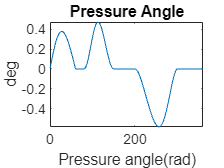


%b
figure
phi=atand((v/omega)/(0.035+y));
fplot(phi);
xlim([0 360]);
title("Pressure Angle")
xlabel("Pressure angle(rad)")
ylabel("deg")

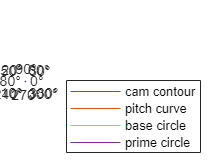


%c
figure
theta=0:0.1:360;
thetarad=deg2rad(theta);
polarplot(thetarad,y(theta)+0.03);
hold on
polarplot(thetarad,y(theta)+0.035);
polarplot(thetarad,0.03+zeros(size(thetarad)));
polarplot(thetarad,0.035+zeros(size(thetarad)));
legend("cam contour","pitch curve","base circle","prime circle");
hold off

%d
tiledlayout(5,2)

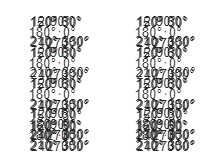

for i=0:pi/6:9*pi/6
    nexttile
    polarplot(thetarad,0.035+zeros(size(thetarad)));
    hold on
    polarplot(thetarad+i,y(theta)+0.03);
    hold off
end